# 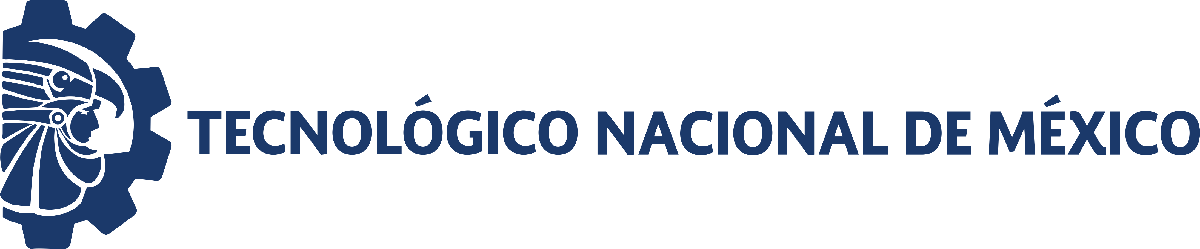

# Combined application of CAR-T cells and chlorambucil for CLL treatment: Insights from nonlinear dynamical systems and model-based design for dose finding

Paul A. Valle¹,  Luis N. Coria¹, Yolocuauhtli Salazar², Corina Plata¹ and Luis A. Ramirez¹

¹Postgraduate Program in Engineering Sciences, BioMath Research Group, Tecnológico Nacional de México / IT Tijuana, Blvd. Alberto Limón Padilla s/n, Tijuana 22454, Mexico

²Postgraduate Program in Engineering. Tecnológico Nacional de México / IT Durango, Blvd. Felipe Pescador 1830 Ote., Durango 34080, Mexico

Corresponding authors: paul.valle@tectijuana.edu.mx; luis.coria@tectijuana.edu.mx

## Parameter values

clc; clear; close all; format shortEng; warning('off','all')

dt = 1E-3;              %Step size
Cmol = 304.212E3;       %Molecular weight of chlorambucil [mg/mol]
IC50 = 61E-6;           %Half maximal inhibitory concentration [umol/L]
wg = 81;                %Average weigth of a person with CLL

k1 = 1.68;              %CLL cancer cells growth rate
k2 = 3E11;              %Maximum leukemia cells carrying capacity
k5 = Cmol*IC50*5;       %Chlorambucil concentration producing 50% of the maximum cytotoxicity on CLL cancer cells

p1 = log(2)/31;         %Death rate of CAR-T cells
p4 = 2.5*k5;            %Chlorambucil concentration producing 50% of the maximum cytotoxicity on CAR-T cells

e1 = log(2)/(1.5/24);   %Decay rate of the chlorambucil drug

CARTperistence = p1/k2; %CAR-T cells persistence threshold

varepsilon1 = 4.799E-2; %Parameter for estimating chlorambucil cytotoxicity
varepsilon2 = 1.693;    %Parameter for estimating chlorambucil cytotoxicity
gamma1 = 1.256E-7;      %Parameter for estimating CAR-T cells cytotoxicity
gamma2 = 1.221E-1;      %Parameter for estimating CAR-T cells cytotoxicity
gamma3 = 6.777E-2;      %Parameter for estimating CAR-T cells cytotoxicity

## *In silico* experimentation

### Depletion and persistence of CAR-T cells, and eradicatin of CLL cells

#### Depletion of CAR-T cells

tend = 2500;
n = round(tend/dt);
p2 = 0.7*CARTperistence;

%Chlorambucil chemotherapy protocol
ChemoProtocol = zeros(n+1,1);
k4 = zeros(n+1,1); %Chlorambucil cytotoxicity rate on CLL cancer cells
p3 = zeros(n+1,1); %Chlorambucil cytotoxicity rate on CAR-T cells
ChemoPars = [k4,p3];

%CAR-T cells immunotherapy protocol
k3 = gamma1 + p1*p2/(gamma2 + p1*p2) + k1*p2/(gamma3 + k1*p2); %CAR-T cells cytotoxicity rate on CLL cells
Immunodose = 1E7;
ImmunoProtocol = zeros(n+1,1);
ImmunoProtocol(1) = Immunodose;

x0 = 1E10;
y0 = ImmunoProtocol(1);
z0 = 0;

P = [k1,k2,k3,k5,p1,p2,p4,e1];
[t1,x1,y1,~,~,~] = digital_twin(x0,y0,z0,tend,P,ImmunoProtocol,ChemoProtocol,ChemoPars,dt);

#### Persistence of CAR-T cells

tend = 2500;
n = round(tend/dt);
p2 = 1.1*CARTperistence;

%Chlorambucil chemotherapy protocol
ChemoProtocol = zeros(n+1,1);
k4 = zeros(n+1,1); %Chlorambucil cytotoxicity rate on CLL cancer cells
p3 = zeros(n+1,1); %Chlorambucil cytotoxicity rate on CAR-T cells
ChemoPars = [k4,p3];

%CAR-T cells immunotherapy protocol
k3 = gamma1 + p1*p2/(gamma2 + p1*p2) + k1*p2/(gamma3 + k1*p2); %CAR-T cells cytotoxicity rate on CLL cells
Immunodose = 1E7;
ImmunoProtocol = zeros(n+1,1);
ImmunoProtocol(1) = Immunodose;

x0 = 1E10;
y0 = ImmunoProtocol(1);
z0 = 0;

P = [k1,k2,k3,k5,p1,p2,p4,e1];
[t2,x2,y2,~,~,~] = digital_twin(x0,y0,z0,tend,P,ImmunoProtocol,ChemoProtocol,ChemoPars,dt);

#### Eradication of CLL cells

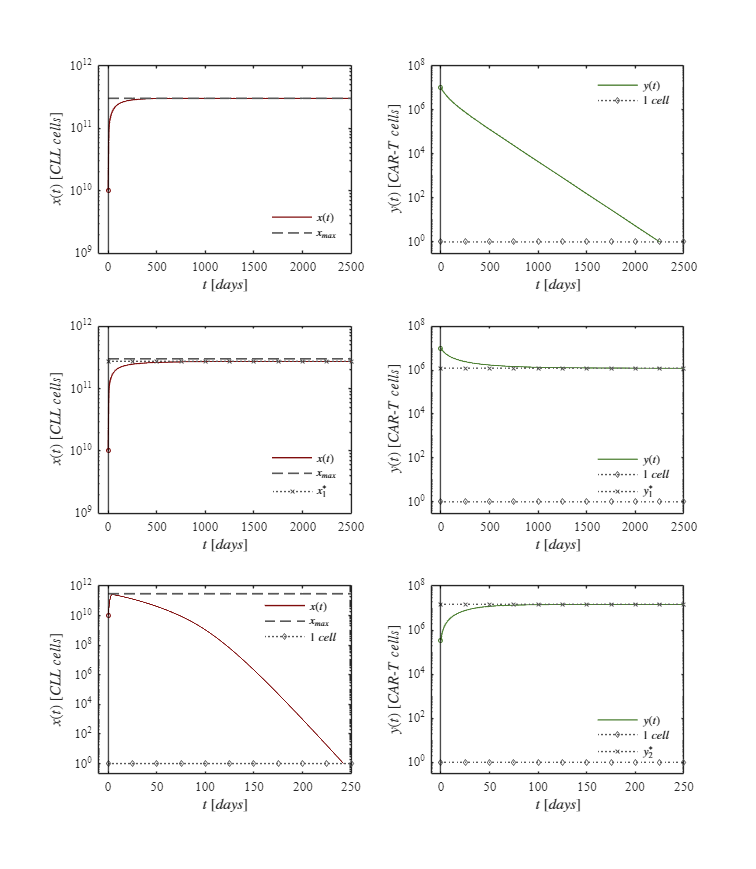

tend = 250;
n = round(tend/dt);
p2 = 1.1*CARTperistence;

%Chlorambucil chemotherapy protocol
ChemoProtocol = zeros(n+1,1);
k4 = zeros(n+1,1); %Chlorambucil cytotoxicity rate on CLL cancer cells
p3 = zeros(n+1,1); %Chlorambucil cytotoxicity rate on CAR-T cells
ChemoPars = [k4,p3];

%CAR-T cells immunotherapy protocol
alpha = 1.1;
k3 = gamma1 + p1*p2/(gamma2 + p1*p2) + k1*p2/(gamma3 + k1*p2); %CAR-T cells cytotoxicity rate on CLL cells
Immunodose = ceil(alpha*k1*p1/k3); %CLL cells eradication condition
ImmunoProtocol = ones(n+1,1)*Immunodose;
ImmunoProtocol(1) = Immunodose;

x0 = 1E10;
y0 = ImmunoProtocol(1);
z0 = 0;

P = [k1,k2,k3,k5,p1,p2,p4,e1]; 
[t3,x3,y3,~,~,~] = digital_twin(x0,y0,z0,tend,P,ImmunoProtocol,ChemoProtocol,ChemoPars,dt);

%Plot
plot_dynamics(t1,x1,y1,t2,x2,y2,t3,x3,y3,k1,k2,k3,p1,p2,y0)

### CLL cells eradication: Dose-escalation chemoimmunotherapy

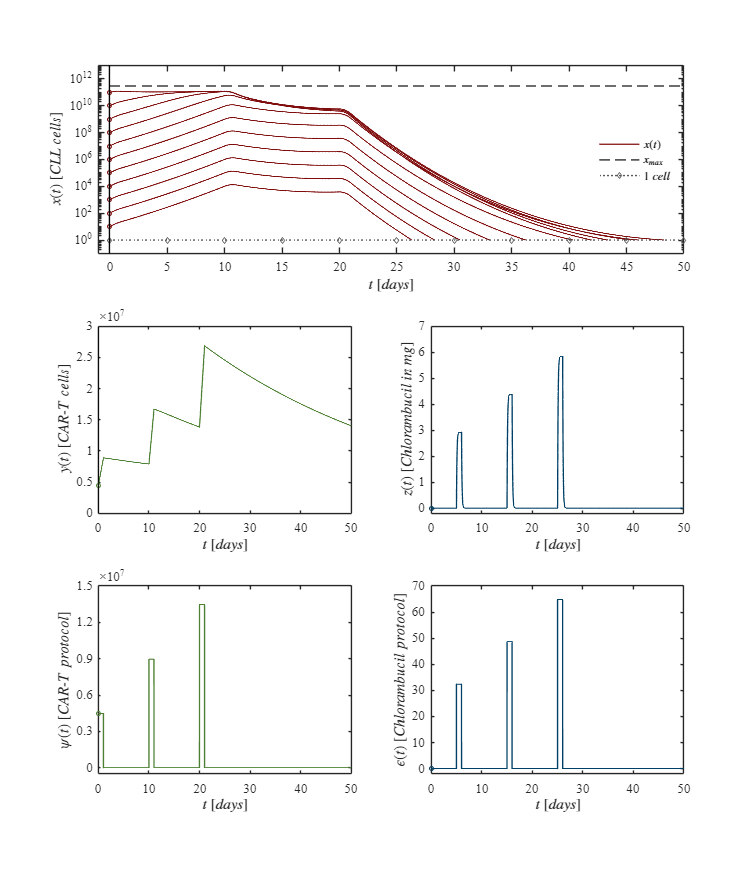

tend = 50;
n = round(tend/dt);
p2 = 1.1*CARTperistence; %Activation rate of CAR-T cells due to encounters with CLL cancer cells

%Chlorambucil chemotherapy protocol
C = [5,15,25]; %Days on which the chemotherapy is applied
ChemoProtocol = zeros(n+1,1);
k4 = zeros(n+1,1);
p3 = zeros(n+1,1);
Chemodose_1 = 0.4*wg; %First chemotherapy dose
ChemoProtocol(round(C(1)/dt):round((C(1)+1)/dt)) = Chemodose_1;
k4(round(C(1)/dt):round((C(1)+1)/dt)) = log10((1 + varepsilon1*Chemodose_1/5)^(1/varepsilon2));
p3(round(C(1)/dt):round((C(1)+1)/dt)) = 0.054*k4(round(C(1)/dt):round((C(1)+1)/dt));
Chemodose_2 = 0.6*wg; %Second chemotherapy dose
ChemoProtocol(round(C(2)/dt):round((C(2)+1)/dt)) = Chemodose_2;
k4(round(C(2)/dt):round((C(2)+1)/dt)) = log10((1 + varepsilon1*Chemodose_2/5)^(1/varepsilon2));
p3(round(C(2)/dt):round((C(2)+1)/dt)) = 0.054*k4(round(C(1)/dt):round((C(1)+1)/dt));
Chemodose_3 = 0.8*wg; %Third chemotherapy dose
ChemoProtocol(round(C(3)/dt):round((C(3)+1)/dt)) = Chemodose_3;
k4(round(C(3)/dt):round((C(3)+1)/dt)) = log10((1 + varepsilon1*Chemodose_3/5)^(1/varepsilon2));
p3(round(C(3)/dt):round((C(3)+1)/dt)) = 0.054*k4(round(C(1)/dt):round((C(1)+1)/dt));

%CAR-T cells immunotherapy protocol
alpha = 45;
k3 = gamma1 + p1*p2/(gamma2 + p1*p2) + k1*p2/(gamma3 + k1*p2); %CAR-T cells cytotoxicity rate on CLL cells
Immunodose = ceil(alpha*k1*p1/k3); %CLL cells eradication condition
I = [0,10,20];  %Days on which the immunotherapy is applied
ImmunoProtocol = zeros(n+1,1);
ImmunoProtocol(1:round(1/dt)) = ceil((1/3)*Immunodose);
ImmunoProtocol(round(I(2)/dt):round((I(2)+1)/dt)) = ceil((2/3)*Immunodose);
ImmunoProtocol(round(I(3)/dt):round((I(3)+1)/dt)) = ceil((3/3)*Immunodose);

%Parameters and initial conditions
P = [k1,k2,k3,k5,p1,p2,p4,e1]; ChemoPars = [k4,p3];
x0 = [1E11 1E10 1E9 1E8 1E7 1E6 1E5 1E4 1E3 1E2 1E1];
y0 = ImmunoProtocol(1);
z0 = 0;

for i = 1:numel(x0)
    [t,x,y,z,Pi,Ci] = digital_twin(x0(i),y0,z0,tend,P,ImmunoProtocol,ChemoProtocol,ChemoPars,dt);
    plot_escaleted_protocolup(t,x,y,z,Pi,Ci,k2)
end

%Chemoimmunotherapy doses
fprintf(['CAR-T cells first dose: ' num2str(ceil((1/3)*Immunodose)),'\n']);...
fprintf(['CAR-T cells second dose: ' num2str(ceil((2/3)*Immunodose)),'\n']);...
fprintf(['CAR-T cells third dose: ' num2str(ceil((3/3)*Immunodose)),'\n']);...
fprintf(['Chlorambucil first dose: ' num2str(0.4*wg),'\n']);...
fprintf(['Chlorambucil second dose: ' num2str(0.6*wg),'\n']);...
fprintf(['Cholarambucil third dose: ' num2str(0.8*wg),'\n']);

CAR-T cells first dose: 4486086


CAR-T cells second dose: 8972172


CAR-T cells third dose: 13458258


Chlorambucil first dose: 32.4


Chlorambucil second dose: 48.6


Cholarambucil third dose: 64.8


### CLL cells eradication: Dose de-escalation chemoimmunotherapy

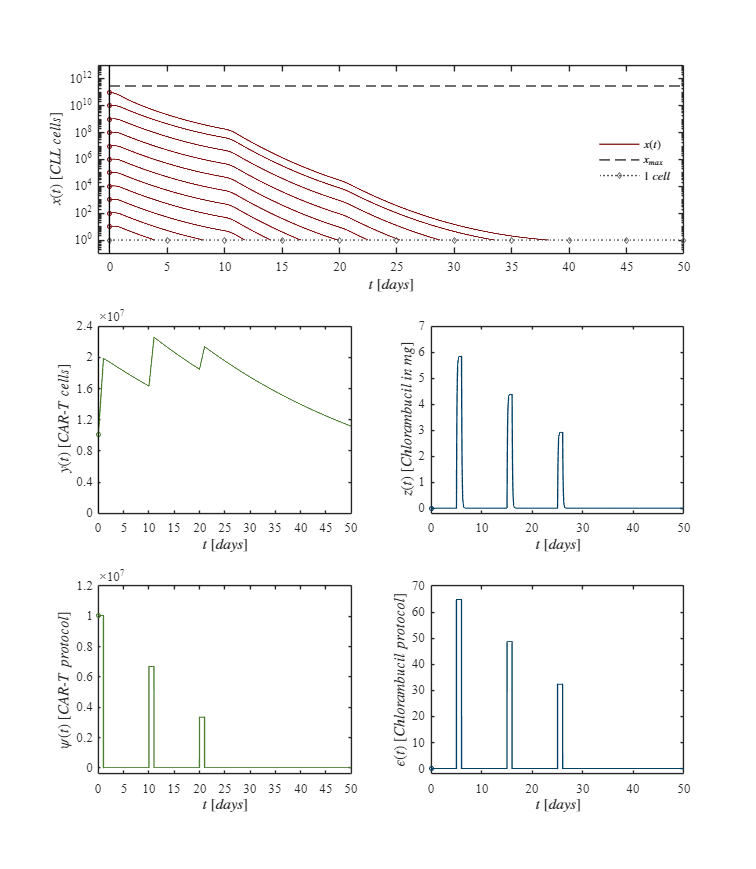

tend = 50;
n = round(tend/dt);
p2 = 1.1*CARTperistence; %Activation rate of CAR-T cells due to encounters with CLL cancer cells

%Chlorambucil chemotherapy protocol
C = [5,15,25]; %Days on which the chemotherapy is applied
ChemoProtocol = zeros(n+1,1);
k4 = zeros(n+1,1);
p3 = zeros(n+1,1);
Chemodose_1 = 0.8*wg; %First chemotherapy dose
ChemoProtocol(round(C(1)/dt):round((C(1)+1)/dt)) = Chemodose_1;
k4(round(C(1)/dt):round((C(1)+1)/dt)) = log10((1 + varepsilon1*Chemodose_1/5)^(1/varepsilon2));
p3(round(C(1)/dt):round((C(1)+1)/dt)) = 0.054*k4(round(C(1)/dt):round((C(1)+1)/dt));
Chemodose_2 = 0.6*wg; %Second chemotherapy dose
ChemoProtocol(round(C(2)/dt):round((C(2)+1)/dt)) = Chemodose_2;
k4(round(C(2)/dt):round((C(2)+1)/dt)) = log10((1 + varepsilon1*Chemodose_2/5)^(1/varepsilon2));
p3(round(C(2)/dt):round((C(2)+1)/dt)) = 0.054*k4(round(C(1)/dt):round((C(1)+1)/dt));
Chemodose_3 = 0.4*wg; %Third chemotherapy dose
ChemoProtocol(round(C(3)/dt):round((C(3)+1)/dt)) = Chemodose_3;
k4(round(C(3)/dt):round((C(3)+1)/dt)) = log10((1 + varepsilon1*Chemodose_3/5)^(1/varepsilon2));
p3(round(C(3)/dt):round((C(3)+1)/dt)) = 0.054*k4(round(C(1)/dt):round((C(1)+1)/dt));

%CAR-T cells immunotherapy protocol
alpha = 33.6;
k3 = gamma1 + p1*p2/(gamma2 + p1*p2) + k1*p2/(gamma3 + k1*p2); %CAR-T cells cytotoxicity rate on CLL cells
Immunodose = ceil(alpha*k1*p1/k3); %CLL cells eradication condition
I = [0,10,20];  %Days on which the immunotherapy is applied
ImmunoProtocol = zeros(n+1,1);
ImmunoProtocol(1:round(1/dt)) = ceil((3/3)*Immunodose);
ImmunoProtocol(round(I(2)/dt):round((I(2)+1)/dt)) = ceil((2/3)*Immunodose);
ImmunoProtocol(round(I(3)/dt):round((I(3)+1)/dt)) = ceil((1/3)*Immunodose);

%Parameters and initial conditions
P = [k1,k2,k3,k5,p1,p2,p4,e1]; ChemoPars = [k4,p3];
x0 = [1E11 1E10 1E9 1E8 1E7 1E6 1E5 1E4 1E3 1E2 1E1];
y0 = ImmunoProtocol(1);
z0 = 0;

for i = 1:numel(x0)
    [t,x,y,z,Pi,Ci] = digital_twin(x0(i),y0,z0,tend,P,ImmunoProtocol,ChemoProtocol,ChemoPars,dt);
    plot_escaleted_protocoldown(t,x,y,z,Pi,Ci,k2)
end

%Chemoimmunotherapy doses
fprintf(['CAR-T cells first dose: ' num2str(ceil((3/3)*Immunodose)),'\n']);...
fprintf(['CAR-T cells second dose: ' num2str(ceil((2/3)*Immunodose)),'\n']);...
fprintf(['CAR-T cells third dose: ' num2str(ceil((1/3)*Immunodose)),'\n']);...
fprintf(['Chlorambucil first dose: ' num2str(0.8*wg),'\n']);...
fprintf(['Chlorambucil second dose: ' num2str(0.6*wg),'\n']);...
fprintf(['Cholarambucil third dose: ' num2str(0.4*wg),'\n']);

CAR-T cells first dose: 10048833


CAR-T cells second dose: 6699222


CAR-T cells third dose: 3349611


Chlorambucil first dose: 64.8


Chlorambucil second dose: 48.6


Cholarambucil third dose: 32.4


### Treatment protocol failure: Dose-escalation chemoimmunotherapy

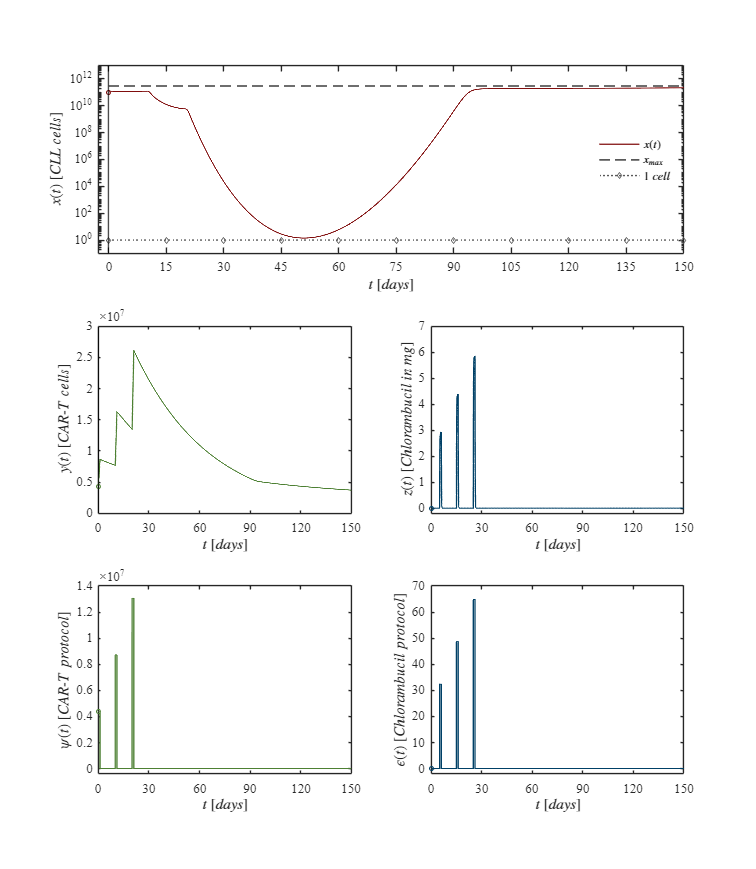

tend = 150;
n = round(tend/dt);
p2 = 1.1*CARTperistence; %Activation rate of CAR-T cells due to encounters with CLL cancer cells

%Chlorambucil chemotherapy protocol
C = [5,15,25]; %Days on which the chemotherapy is applied
ChemoProtocol = zeros(n+1,1);
k4 = zeros(n+1,1);
p3 = zeros(n+1,1);
Chemodose_1 = 0.4*wg; %First chemotherapy dose
ChemoProtocol(round(C(1)/dt):round((C(1)+1)/dt)) = Chemodose_1;
k4(round(C(1)/dt):round((C(1)+1)/dt)) = log10((1 + varepsilon1*Chemodose_1/5)^(1/varepsilon2));
p3(round(C(1)/dt):round((C(1)+1)/dt)) = 0.054*k4(round(C(1)/dt):round((C(1)+1)/dt));
Chemodose_2 = 0.6*wg; %Second chemotherapy dose
ChemoProtocol(round(C(2)/dt):round((C(2)+1)/dt)) = Chemodose_2;
k4(round(C(2)/dt):round((C(2)+1)/dt)) = log10((1 + varepsilon1*Chemodose_2/5)^(1/varepsilon2));
p3(round(C(2)/dt):round((C(2)+1)/dt)) = 0.054*k4(round(C(1)/dt):round((C(1)+1)/dt));
Chemodose_3 = 0.8*wg; %Third chemotherapy dose
ChemoProtocol(round(C(3)/dt):round((C(3)+1)/dt)) = Chemodose_3;
k4(round(C(3)/dt):round((C(3)+1)/dt)) = log10((1 + varepsilon1*Chemodose_3/5)^(1/varepsilon2));
p3(round(C(3)/dt):round((C(3)+1)/dt)) = 0.054*k4(round(C(1)/dt):round((C(1)+1)/dt));

%CAR-T cells immunotherapy protocol
alpha = 43.7;
k3 = gamma1 + p1*p2/(gamma2 + p1*p2) + k1*p2/(gamma3 + k1*p2); %CAR-T cells cytotoxicity rate on CLL cells
Immunodose = ceil(alpha*k1*p1/k3); %CLL cells eradication condition
I = [0,10,20];  %Days on which the immunotherapy is applied
ImmunoProtocol = zeros(n+1,1);
ImmunoProtocol(1:round(1/dt)) = ceil((1/3)*Immunodose);
ImmunoProtocol(round(I(2)/dt):round((I(2)+1)/dt)) = ceil((2/3)*Immunodose);
ImmunoProtocol(round(I(3)/dt):round((I(3)+1)/dt)) = ceil((3/3)*Immunodose);

P = [k1,k2,k3,k5,p1,p2,p4,e1]; ChemoPars = [k4,p3];
x0 = 1E11;
y0 = ImmunoProtocol(1);
z0 = 0;
[t,x,y,z,Pi,Ci] = digital_twin(x0,y0,z0,tend,P,ImmunoProtocol,ChemoProtocol,ChemoPars,dt);
plot_failureup(t,x,y,z,Pi,Ci,k2)

%Chemoimmunotherapy doses
fprintf(['CAR-T cells first dose: ' num2str(ceil((1/3)*Immunodose)),'\n']);...
fprintf(['CAR-T cells second dose: ' num2str(ceil((2/3)*Immunodose)),'\n']);...
fprintf(['CAR-T cells third dose: ' num2str(ceil((3/3)*Immunodose)),'\n']);...
fprintf(['Chlorambucil first dose: ' num2str(0.4*wg),'\n']);...
fprintf(['Chlorambucil second dose: ' num2str(0.6*wg),'\n']);...
fprintf(['Cholarambucil third dose: ' num2str(0.8*wg),'\n']);

CAR-T cells first dose: 4356488


CAR-T cells second dose: 8712976


CAR-T cells third dose: 13069464


Chlorambucil first dose: 32.4


Chlorambucil second dose: 48.6


Cholarambucil third dose: 64.8


### Treatment protocol failure: Dose de-escalation chemoimmunotherapy

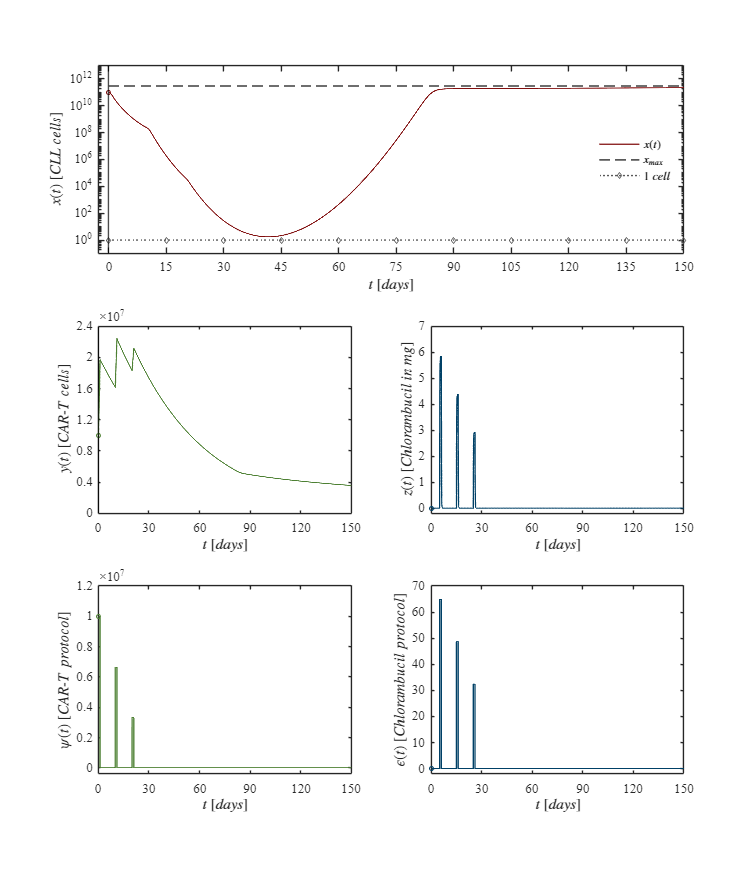

tend = 150;
n = round(tend/dt);
p2 = 1.1*CARTperistence; %Activation rate of CAR-T cells due to encounters with CLL cancer cells

%Chlorambucil chemotherapy protocol
C = [5,15,25]; %Days on which the chemotherapy is applied
ChemoProtocol = zeros(n+1,1);
k4 = zeros(n+1,1);
p3 = zeros(n+1,1);
Chemodose_1 = 0.8*wg; %First chemotherapy dose
ChemoProtocol(round(C(1)/dt):round((C(1)+1)/dt)) = Chemodose_1;
k4(round(C(1)/dt):round((C(1)+1)/dt)) = log10((1 + varepsilon1*Chemodose_1/5)^(1/varepsilon2));
p3(round(C(1)/dt):round((C(1)+1)/dt)) = 0.054*k4(round(C(1)/dt):round((C(1)+1)/dt));
Chemodose_2 = 0.6*wg; %Second chemotherapy dose
ChemoProtocol(round(C(2)/dt):round((C(2)+1)/dt)) = Chemodose_2;
k4(round(C(2)/dt):round((C(2)+1)/dt)) = log10((1 + varepsilon1*Chemodose_2/5)^(1/varepsilon2));
p3(round(C(2)/dt):round((C(2)+1)/dt)) = 0.054*k4(round(C(1)/dt):round((C(1)+1)/dt));
Chemodose_3 = 0.4*wg; %Third chemotherapy dose
ChemoProtocol(round(C(3)/dt):round((C(3)+1)/dt)) = Chemodose_3;
k4(round(C(3)/dt):round((C(3)+1)/dt)) = log10((1 + varepsilon1*Chemodose_3/5)^(1/varepsilon2));
p3(round(C(3)/dt):round((C(3)+1)/dt)) = 0.054*k4(round(C(1)/dt):round((C(1)+1)/dt));

%CAR-T cells immunotherapy protocol
alpha = 33.3;
k3 = gamma1 + p1*p2/(gamma2 + p1*p2) + k1*p2/(gamma3 + k1*p2); %CAR-T cells cytotoxicity rate on CLL cells
Immunodose = ceil(alpha*k1*p1/k3); %CLL cells eradication condition
I = [0,10,20];  %Days on which the immunotherapy is applied
ImmunoProtocol = zeros(n+1,1);
ImmunoProtocol(1:round(1/dt)) = ceil((3/3)*Immunodose);
ImmunoProtocol(round(I(2)/dt):round((I(2)+1)/dt)) = ceil((2/3)*Immunodose);
ImmunoProtocol(round(I(3)/dt):round((I(3)+1)/dt)) = ceil((1/3)*Immunodose);

P = [k1,k2,k3,k5,p1,p2,p4,e1]; ChemoPars = [k4,p3];
x0 = 1E11;
y0 = ImmunoProtocol(1);
z0 = 0;
[t,x,y,z,Pi,Ci] = digital_twin(x0,y0,z0,tend,P,ImmunoProtocol,ChemoProtocol,ChemoPars,dt);
plot_failuredown(t,x,y,z,Pi,Ci,k2)

%Chemoimmunotherapy doses
fprintf(['CAR-T cells first dose: ' num2str(ceil((3/3)*Immunodose)),'\n']);...
fprintf(['CAR-T cells second dose: ' num2str(ceil((2/3)*Immunodose)),'\n']);...
fprintf(['CAR-T cells third dose: ' num2str(ceil((1/3)*Immunodose)),'\n']);...
fprintf(['Chlorambucil first dose: ' num2str(0.8*wg),'\n']);...
fprintf(['Chlorambucil second dose: ' num2str(0.6*wg),'\n']);...
fprintf(['Cholarambucil third dose: ' num2str(0.4*wg),'\n']);

CAR-T cells first dose: 9959111


CAR-T cells second dose: 6639408


CAR-T cells third dose: 3319704


Chlorambucil first dose: 64.8


Chlorambucil second dose: 48.6


Cholarambucil third dose: 32.4


### CLL cells eradication through chemotherapy

tend = 50;
n = round(tend/dt);

dt = 1E-3;              %Step size
Cmol = 304.212E3;       %Molecular weight of chlorambucil [mg/mol]
IC50 = 61E-6;           %Half maximal inhibitory concentration [umol/L]
wg = 81;                %Average weigth of a person with CLL

k1 = 1.68/10;           %CLL cancer cells growth rate
k2 = 3E11;              %Maximum leukemia cells carrying capacity
k5 = 0.5*Cmol*IC50*5;   %Chlorambucil concentration producing 50% of the maximum cytotoxicity on CLL cancer cells

p1 = log(2)/31;         %Death rate of CAR-T cells
p4 = 2.5*Cmol*IC50*5;   %Chlorambucil concentration producing 50% of the maximum cytotoxicity on CAR-T cells

e1 = log(2)/(1.5/24);   %Decay rate of the chlorambucil drug

CARTperistence = p1/k2; %CAR-T cells persistence threshold

varepsilon1 = 4.799E-2; %Parameter for estimating chlorambucil cytotoxicity
varepsilon2 = 1.693;    %Parameter for estimating chlorambucil cytotoxicity
gamma1 = 1.256E-7;      %Parameter for estimating CAR-T cells cytotoxicity
gamma2 = 1.221E-1;      %Parameter for estimating CAR-T cells cytotoxicity
gamma3 = 6.777E-2;      %Parameter for estimating CAR-T cells cytotoxicity

p2 = 1.1*CARTperistence; %Activation rate of CAR-T cells due to encounters with CLL cancer cells

%Chlorambucil chemotherapy protocol
Chemodose = 13*wg; %Chemotherapy unique constant dose
fprintf(['Chemotherapy constant dose: ', num2str(Chemodose), ' mg'])

Chemotherapy constant dose: 1053 mg

ChemoProtocol = ones(n+1,1)*Chemodose;
k4 = ones(n+1,1)*(log10(1 + varepsilon1*Chemodose/5)^(1/varepsilon2));
p3 = 0.054*k4;
constraint = max(e1*k1*k5/(k4-k1));
fprintf(['Chemotherapy dose condition for CLL cells eradication: ', num2str(constraint), ' mg'])

Chemotherapy dose condition for CLL cells eradication: 100.663 mg

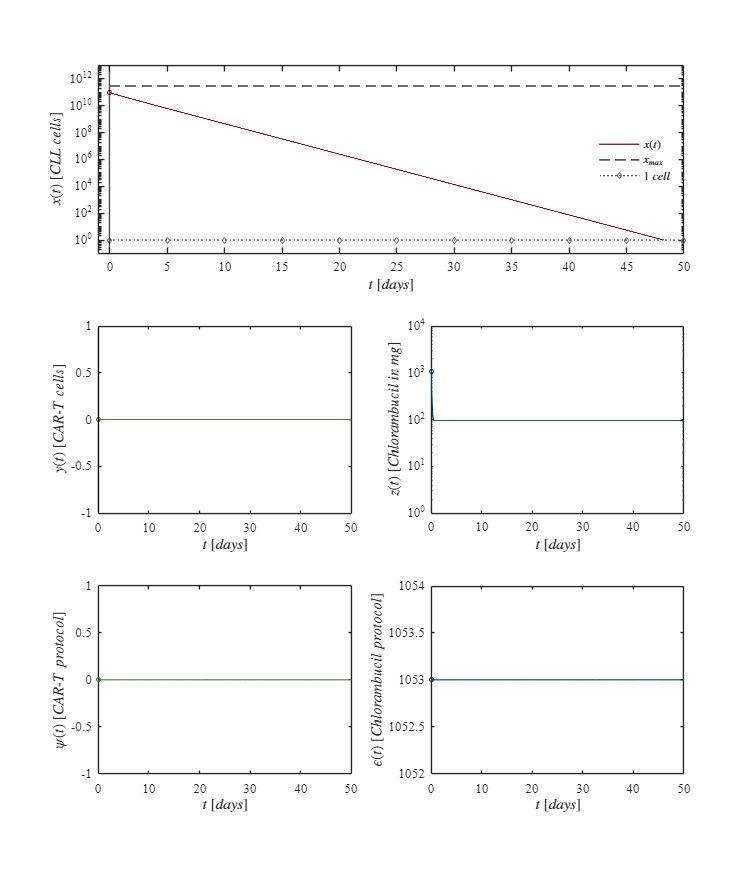

%CAR-T cells immunotherapy protocol
alpha = 45;
k3 = gamma1 + p1*p2/(gamma2 + p1*p2) + k1*p2/(gamma3 + k1*p2); %CAR-T cells cytotoxicity rate on CLL cells
ImmunoProtocol = zeros(n+1,1);

%Parameters and initial conditions
P = [k1,k2,k3,k5,p1,p2,p4,e1]; ChemoPars = [k4,p3];
x0 = 1E11;
y0 = ImmunoProtocol(1);
z0 = ChemoProtocol(1);

[t,x,y,z,Pi,Ci] = digital_twin(x0,y0,z0,tend,P,ImmunoProtocol,ChemoProtocol,ChemoPars,dt);
plot_chemo_protocol(t,x,y,z,Pi,Ci,k2)

## Functions

### Mathematical model

function [ti,xi,yi,zi,Pi,Ei] = digital_twin(x0,y0,z0,tend,P,pt,et,C,dt)
    n = round(tend/dt);
    time = (0:dt:tend)';

    k1 = P(1); k2 = P(2); k3 = P(3); k5 = P(4);
    p1 = P(5); p2 = P(6); p4 = P(7);
    e1 = P(8);
    k4 = C(:,1); p3 = C(:,2);
    
    x = zeros(n+1,1); x(1) = x0;
    y = zeros(n+1,1); y(1) = y0;
    z = zeros(n+1,1); z(1) = z0;
    
    for i = 1:n
        if x(i) >= 1 && y(i) >= 1
        x(i+1) = x(i) + (k1*x(i)*(1 - x(i)/k2) - k3*x(i)*y(i) - k4(i)*x(i)*z(i)/(k5 + z(i)))*dt;
        y(i+1) = y(i) + (pt(i) - p1*y(i) + p2*x(i)*y(i) - p3(i)*y(i)*z(i)/(p4 + z(i)))*dt;
        z(i+1) = z(i) + (et(i) - e1*z(i))*dt;
    
        elseif x(i) < 1 && y(i) >= 1
        x(i+1) = 0;
        y(i+1) = y(i) + (pt(i) - p1*y(i) + p2*x(i)*y(i) - p3(i)*y(i)*z(i)/(p4 + z(i)))*dt;
        z(i+1) = z(i) + (et(i) - e1*z(i))*dt;

        elseif x(i) >= 1 && y(i) < 1
        x(i+1) = x(i) + (k1*x(i)*(1 - x(i)/k2) - k3*x(i)*y(i) - k4(i)*x(i)*z(i)/(k5 + z(i)))*dt;
        y(i+1) = 0;
        z(i+1) = z(i) + (et(i) - e1*z(i))*dt;
    
        elseif x(i) < 1 && y(i) < 1
        x(i+1) = 0;
        y(i+1) = 0;
        z(i+1) = z(i) + (et(i) - e1*z(i))*dt;
        end
    end
    
    i = 100; j = round(1/(dt*i));
    ti = time(1:j:end); Pi = pt(1:j:end);   Ei = et(1:j:end);
    xi = x(1:j:end);    yi = y(1:j:end);    zi = z(1:j:end);
end

### Figure: Depletion and persistence of CAR-T cells, eradication of CLL cells

function plot_dynamics(t1,x1,y1,t2,x2,y2,t3,x3,y3,k1,k2,k3,p1,p2,p)
    FS = 10;
    ti = 0:250:2500;

    set (figure(1),'color','w')
    set(gcf,'units','centimeters','position',[1,1,20,23])

    subplot(3,2,1)
    set(gca,'YScale','log'); box on; grid off; hold on
    xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
    ylabel({'$x(t)$ $[CLL$ $cells]$'},'interpreter','latex','fontsize',FS)
    set(gca,'fontname','times new roman','fontsize',FS)
    semilogy(t1,x1,'-','linewidth',1,'color',[0.5,0.05,0.05])
    plot(ti,k2*ones(length(ti),1),'--','linewidth',1.25,'color',[0.35,0.35,0.35])
    plot(t1(1),x1(1),'o','linewidth',0.75,'markersize',3,'color',[0.5,0.05,0.05])
    xline(0,'-','color','k')
    L = legend('$x(t)$','$x_{max}$');
    set(L,'interpreter','latex','fontsize',FS-1,'box','off','location','southeast')
    xlim([-100 2500]); xticks(0:500:2500)
    ylim([1E9 1E12]);
    yticks([1E9 1E10 1E11 1E12]); set(gca,'YMinorTick','off')

    subplot(3,2,2)
    set(gca,'YScale','log'); box on; grid off; hold on
    xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
    ylabel({'$y(t)$ $[CAR$-$T$ $cells]$'},'interpreter','latex','fontsize',FS)
    set(gca,'fontname','times new roman','fontsize',FS)
    semilogy(t1,y1,'-','linewidth',1,'color',[0.3,0.5,0.2])
    plot(ti,ones(length(ti),1),':d','linewidth',0.75,'markersize',3,'color',[0.35,0.35,0.35])
    plot(t1(1),y1(1),'o','linewidth',0.75,'markersize',3,'color',[0.3,0.5,0.2])
    xline(0,'-','color','k')
    L = legend('$y(t)$','$1$ $cell$');
    set(L,'interpreter','latex','fontsize',FS-1,'box','off','location','northeast')
    xlim([-100 2500]); xticks(0:500:2500)
    ylim([3E-1 1E8]);
    yticks([1E0 1E2 1E4 1E6 1E8]); set(gca,'YMinorTick','off')
    
    ti = 0:250:2500;
    subplot(3,2,3)
    set(gca,'YScale','log'); box on; grid off; hold on
    xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
    ylabel({'$x(t)$ $[CLL$ $cells]$'},'interpreter','latex','fontsize',FS)
    set(gca,'fontname','times new roman','fontsize',FS)
    semilogy(t2,x2,'-','linewidth',1,'color',[0.5,0.05,0.05])
    plot(ti,k2*ones(length(ti),1),'--','linewidth',1.25,'color',[0.35,0.35,0.35])
    plot(ti,p1/p2*ones(length(ti),1),':x','linewidth',0.75,'markersize',4,'color',[0.35,0.35,0.35])
    plot(t2(1),x2(1),'o','linewidth',0.75,'markersize',3,'color',[0.5,0.05,0.05])
    xline(0,'-','color','k')
    L = legend('$x(t)$','$x_{max}$','$x^*_1$');
    set(L,'interpreter','latex','fontsize',FS-1,'box','off','location','southeast')
    xlim([-100 2500]); xticks(0:500:2500)
    ylim([1E9 1E12]);
    yticks([1E9 1E10 1E11 1E12]); set(gca,'YMinorTick','off')

    subplot(3,2,4)
    set(gca,'YScale','log'); box on; grid off; hold on
    xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
    ylabel({'$y(t)$ $[CAR$-$T$ $cells]$'},'interpreter','latex','fontsize',FS)
    set(gca,'fontname','times new roman','fontsize',FS)
    plot(t2,y2,'-','linewidth',1,'color',[0.3,0.5,0.2])
    plot(ti,ones(length(ti),1),':d','linewidth',0.75,'markersize',3,'color',[0.35,0.35,0.35])
    plot(ti,k1*(k2*p2-p1)/(k2*k3*p2)*ones(length(ti),1),':x','linewidth',0.75,'markersize',4,'color',[0.35,0.35,0.35])
    plot(t2(1),y2(1),'o','linewidth',0.75,'markersize',3,'color',[0.3,0.5,0.2])
    xline(0,'-','color','k')
    L = legend('$y(t)$','$1$ $cell$','$y^*_1$');
    set(L,'interpreter','latex','fontsize',FS-1,'box','off','location','southeast')
    xlim([-100 2500]); xticks(0:500:2500)
    ylim([3E-1 1E8]);
    yticks([1E0 1E2 1E4 1E6 1E8]); set(gca,'YMinorTick','off')
    
    ti = 0:25:250;
    subplot(3,2,5)
    set(gca,'YScale','log'); box on; grid off; hold on
    xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
    ylabel({'$x(t)$ $[CLL$ $cells]$'},'interpreter','latex','fontsize',FS)
    set(gca,'fontname','times new roman','fontsize',FS)
    semilogy(t3,x3,'-','linewidth',1,'color',[0.5,0.05,0.05])
    plot(ti,k2*ones(length(ti),1),'--','linewidth',1.25,'color',[0.35,0.35,0.35])
    plot(ti,ones(length(ti),1),':d','linewidth',0.75,'markersize',3,'color',[0.35,0.35,0.35])
    plot(t3(1),x3(1),'o','linewidth',0.75,'markersize',3,'color',[0.5,0.05,0.05])
    xline(0,'-','color','k')
    L = legend('$x(t)$','$x_{max}$','$1$ $cell$');
    set(L,'interpreter','latex','fontsize',FS-1,'box','off','location','northeast')
    xlim([-10 250]); xticks(0:50:250)
    ylim([2E-1 1E12])
    yticks([1E0 1E2 1E4 1E6 1E8 1E10 1E12]); set(gca,'YMinorTick','off')

    subplot(3,2,6)
    set(gca,'YScale','log'); box on; grid off; hold on
    xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
    ylabel({'$y(t)$ $[CAR$-$T$ $cells]$'},'interpreter','latex','fontsize',FS)
    set(gca,'fontname','times new roman','fontsize',FS)
    plot(t3,y3,'-','linewidth',1,'color',[0.3,0.5,0.2])
    plot(ti,ones(length(ti),1),':d','linewidth',0.75,'markersize',3,'color',[0.35,0.35,0.35])
    plot(ti,p/p1*ones(length(ti),1),':x','linewidth',0.75,'markersize',4,'color',[0.35,0.35,0.35])
    plot(t3(1),y3(1),'o','linewidth',0.75,'markersize',3,'color',[0.3,0.5,0.2])
    xline(0,'-','color','k')
    L = legend('$y(t)$','$1$ $cell$','$y^*_2$');
    set(L,'interpreter','latex','fontsize',FS-1,'box','off','location','southeast')
    xlim([-10 250]); xticks(0:50:250)
    ylim([3E-1 1E8]);
    yticks([1E0 1E2 1E4 1E6 1E8]); set(gca,'YMinorTick','off')

    exportgraphics(gcf,'insilico_dynamics.pdf','ContentType','vector')
end

### Figure: Chemoimmunotherapy protocols

function plot_escaleted_protocolup(t,x,y,z,pt,et,k2)
    FS = 10;
    ti = 0:5:50;

    set (figure(3),'color','w')
    set(gcf,'units','centimeters','position',[1,1,20,23])

    subplot(3,2,[1 2])
    set(gca,'YScale','log'); box on; grid off; hold on
    xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
    ylabel({'$x(t)$ $[CLL$ $cells]$'},'interpreter','latex','fontsize',FS)
    set(gca,'fontname','times new roman','fontsize',FS)
    semilogy(t,x,'-','linewidth',1,'color',[0.5,0.05,0.05])
    plot(ti,k2*ones(length(ti),1),'--','linewidth',1.25,'color',[0.35,0.35,0.35])
    plot(ti,ones(length(ti),1),':d','linewidth',0.75,'markersize',3,'color',[0.35,0.35,0.35])
    plot(t(1),x(1),'o','linewidth',0.75,'markersize',3,'color',[0.5,0.05,0.05])
    xline(0,'-','color','k')
    L = legend('$x(t)$','$x_{max}$','$1$ $cell$');
    set(L,'interpreter','latex','fontsize',FS-1,'box','off','location','best')
    xlim([-1 50]); xticks(0:5:50)
    ylim([1E-1 1E13]);
    yticks([1E0 1E2 1E4 1E6 1E8 1E10 1E12]); set(gca,'YMinorTick','off')

    if x(1) == 1E11

        subplot(3,2,3)
        box on; hold on
        xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
        ylabel({'$y(t)$ $[CAR$-$T$ $cells]$'},'interpreter','latex','fontsize',FS)
        set(gca,'fontname','times new roman','fontsize',FS)
        plot(t,y,'-','linewidth',1,'color',[0.3,0.5,0.2])
        plot(t(1),y(1),'o','linewidth',0.75,'markersize',3,'color',[0.3,0.5,0.2])
        xline(0,'-','color','k')
        xlim([0 50]); xticks(0:10:50)
        ylim([0 3E7]); yticks(0:0.5E7:3E7); yexp = gca; yexp.YAxis.Exponent = 7;
    
        subplot(3,2,5)
        box on; hold on
        xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
        ylabel('$\psi (t)$ $[CAR$-$T$ $protocol]$','interpreter','latex','fontsize',FS)
        set(gca,'fontname','times new roman','fontsize',FS)
        plot(t,pt,'-','linewidth',1,'color', [0.3,0.5,0.2])
        plot(t(1),pt(1),'o','linewidth',0.75,'markersize',3,'color',[0.3,0.5,0.2])
        xlim([0 50]); xticks(0:10:50)
        ylim([-0.05E7 1.5E7]); yticks(0:0.3E7:1.5E7); yexp = gca; yexp.YAxis.Exponent = 7;
    
        subplot(3,2,4)
        box on; hold on
        xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
        ylabel('$z(t)$ $[Chlorambucil$ $in$ $mg]$','interpreter','latex','fontsize',FS)
        set(gca,'fontname','times new roman','fontsize',FS)
        plot(t,z,'-','linewidth',1,'color',[0,0.25,0.4])
        plot(t(1),z(1),'o','linewidth',0.75,'markersize',3,'color',[0,0.25,0.4])
        xlim([0 50]); xticks(0:10:50)
        ylim([-0.2 7]); yticks(0:1:7)
    
        subplot(3,2,6)
        box on; hold on
        xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
        ylabel('$\epsilon (t)$ $[Chlorambucil$ $protocol]$','interpreter','latex','fontsize',FS)
        set(gca,'fontname','times new roman','fontsize',FS)
        plot(t,et,'-','linewidth',1,'color',[0,0.25,0.4])
        plot(t(1),et(1),'o','linewidth',0.75,'markersize',3,'color',[0,0.25,0.4])
        xlim([0 50]); xticks(0:10:50)
        ylim([-2 70]); yticks(0:10:70)

    elseif x(1) == 1E1
        exportgraphics(gcf,'insilico_escalated_protocol_up.pdf','ContentType','vector')  
    end
end

function plot_escaleted_protocoldown(t,x,y,z,pt,et,k2)
    FS = 10;
    ti = 0:5:50;

    set (figure(4),'color','w')
    set(gcf,'units','centimeters','position',[1,1,20,23])

    subplot(3,2,[1 2])
    set(gca,'YScale','log'); box on; grid off; hold on
    xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
    ylabel({'$x(t)$ $[CLL$ $cells]$'},'interpreter','latex','fontsize',FS)
    set(gca,'fontname','times new roman','fontsize',FS)
    semilogy(t,x,'-','linewidth',1,'color',[0.5,0.05,0.05])
    plot(ti,k2*ones(length(ti),1),'--','linewidth',1.25,'color',[0.35,0.35,0.35])
    plot(ti,ones(length(ti),1),':d','linewidth',0.75,'markersize',3,'color',[0.35,0.35,0.35])
    plot(t(1),x(1),'o','linewidth',0.75,'markersize',3,'color',[0.5,0.05,0.05])
    xline(0,'-','color','k')
    L = legend('$x(t)$','$x_{max}$','$1$ $cell$');
    set(L,'interpreter','latex','fontsize',FS-1,'box','off','location','best')
    xlim([-1 50]); xticks(0:5:50)
    ylim([1E-1 1E13]);
    yticks([1E0 1E2 1E4 1E6 1E8 1E10 1E12]); set(gca,'YMinorTick','off')
    
    if x(1) == 1E11
        subplot(3,2,3)
        box on; hold on
        xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
        ylabel({'$y(t)$ $[CAR$-$T$ $cells]$'},'interpreter','latex','fontsize',FS)
        set(gca,'fontname','times new roman','fontsize',FS)
        plot(t,y,'-','linewidth',1,'color',[0.3,0.5,0.2])
        plot(t(1),y(1),'o','linewidth',0.75,'markersize',3,'color',[0.3,0.5,0.2])
        xline(0,'-','color','k')
        xlim([0 50]); xticks(0:5:50)
        ylim([0 2.4E7]); yticks(0:0.4E7:2.4E7); yexp = gca; yexp.YAxis.Exponent = 7;
    
        subplot(3,2,5)
        box on; hold on
        xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
        ylabel('$\psi (t)$ $[CAR$-$T$ $protocol]$','interpreter','latex','fontsize',FS)
        set(gca,'fontname','times new roman','fontsize',FS)
        plot(t,pt,'-','linewidth',1,'color', [0.3,0.5,0.2])
        plot(t(1),pt(1),'o','linewidth',0.75,'markersize',3,'color',[0.3,0.5,0.2])
        xlim([0 50]); xticks(0:5:50)
        ylim([-0.04E7 1.2E7]); yticks(0:0.2E7:1.2E7); yexp = gca; yexp.YAxis.Exponent = 7;
    
        subplot(3,2,4)
        box on; hold on
        xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
        ylabel('$z(t)$ $[Chlorambucil$ $in$ $mg]$','interpreter','latex','fontsize',FS)
        set(gca,'fontname','times new roman','fontsize',FS)
        plot(t,z,'-','linewidth',1,'color',[0,0.25,0.4])
        plot(t(1),z(1),'o','linewidth',0.75,'markersize',3,'color',[0,0.25,0.4])
        xlim([0 50]); xticks(0:10:50)
        ylim([-0.2 7]); yticks(0:1:7)
    
        subplot(3,2,6)
        box on; hold on
        xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
        ylabel('$\epsilon (t)$ $[Chlorambucil$ $protocol]$','interpreter','latex','fontsize',FS)
        set(gca,'fontname','times new roman','fontsize',FS)
        plot(t,et,'-','linewidth',1,'color',[0,0.25,0.4])
        plot(t(1),et(1),'o','linewidth',0.75,'markersize',3,'color',[0,0.25,0.4])
        xlim([0 50]); xticks(0:10:50)
        ylim([-2 70]); yticks(0:10:70)
    
    elseif x(1) == 1E1
        exportgraphics(gcf,'insilico_escalated_protocol_down.pdf','ContentType','vector')
    end
end

### Figure: Treatment failure

function plot_failureup(t,x,y,z,pt,et,k2)
    FS = 10;
    ti = 0:15:150;

    set (figure(5),'color','w')
    set(gcf,'units','centimeters','position',[1,1,20,23])

    subplot(3,2,[1 2])
    set(gca,'YScale','log'); set(gca,'yminortick','off'); box on; grid off; hold on
    xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
    ylabel({'$x(t)$ $[CLL$ $cells]$'},'interpreter','latex','fontsize',FS)
    set(gca,'fontname','times new roman','fontsize',FS)
    semilogy(t,x,'-','linewidth',1,'color',[0.5,0.05,0.05])
    plot(ti,k2*ones(length(ti),1),'--','linewidth',1.25,'color',[0.35,0.35,0.35])
    plot(ti,ones(length(ti),1),':d','linewidth',0.75,'markersize',3,'color',[0.35,0.35,0.35])
    plot(t(1),x(1),'o','linewidth',0.75,'markersize',3,'color',[0.5,0.05,0.05])
    xline(0,'-','color','k')
    L = legend('$x(t)$','$x_{max}$','$1$ $cell$');
    set(L,'interpreter','latex','fontsize',FS-1,'box','off','location','best')
    xlim([-2.7 150]); xticks(0:15:150)
    ylim([1E-1 1E13]);
    yticks([1E0 1E2 1E4 1E6 1E8 1E10 1E12]); set(gca,'YMinorTick','off')

    subplot(3,2,3)
    box on; hold on
    xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
    ylabel({'$y(t)$ $[CAR$-$T$ $cells]$'},'interpreter','latex','fontsize',FS)
    set(gca,'fontname','times new roman','fontsize',FS)
    plot(t,y,'-','linewidth',1,'color',[0.3,0.5,0.2])
    plot(t(1),y(1),'o','linewidth',0.75,'markersize',3,'color',[0.3,0.5,0.2])
    xline(0,'-','color','k')
    xlim([0 150]); xticks(0:30:150)
    ylim([0 3E7]); yticks(0:0.5E7:3E7); yexp = gca; yexp.YAxis.Exponent = 7;

    subplot(3,2,5)
    box on; hold on
    xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
    ylabel('$\psi (t)$ $[CAR$-$T$ $protocol]$','interpreter','latex','fontsize',FS)
    set(gca,'fontname','times new roman','fontsize',FS)
    plot(t,pt,'-','linewidth',1,'color', [0.3,0.5,0.2])
    plot(t(1),pt(1),'o','linewidth',0.75,'markersize',3,'color',[0.3,0.5,0.2])
    xlim([0 150]); xticks(0:30:150)
    ylim([-0.04E7 1.4E7]); yticks(0:0.2E7:1.4E7); yexp = gca; yexp.YAxis.Exponent = 7;

    subplot(3,2,4)
    box on; hold on
    xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
    ylabel('$z(t)$ $[Chlorambucil$ $in$ $mg]$','interpreter','latex','fontsize',FS)
    set(gca,'fontname','times new roman','fontsize',FS)
    plot(t,z,'-','linewidth',1,'color',[0,0.25,0.4])
    plot(t(1),z(1),'o','linewidth',0.75,'markersize',3,'color',[0,0.25,0.4])
    xlim([0 150]); xticks(0:30:150)
    ylim([-0.2 7]); yticks(0:1:7)

    subplot(3,2,6)
    box on; hold on
    xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
    ylabel('$\epsilon (t)$ $[Chlorambucil$ $protocol]$','interpreter','latex','fontsize',FS)
    set(gca,'fontname','times new roman','fontsize',FS)
    plot(t,et,'-','linewidth',1,'color',[0,0.25,0.4])
    plot(t(1),et(1),'o','linewidth',0.75,'markersize',3,'color',[0,0.25,0.4])
    xlim([0 150]); xticks(0:30:150)
    ylim([-2 70]); yticks(0:10:70)

    exportgraphics(gcf,'insilico_failure_up.pdf','ContentType','vector')
end

function plot_failuredown(t,x,y,z,pt,et,k2)
    FS = 10;
    ti = 0:15:150;

    set (figure(6),'color','w')
    set(gcf,'units','centimeters','position',[1,1,20,23])

    subplot(3,2,[1 2])
    set(gca,'YScale','log'); set(gca,'yminortick','off'); box on; grid off; hold on
    xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
    ylabel({'$x(t)$ $[CLL$ $cells]$'},'interpreter','latex','fontsize',FS)
    set(gca,'fontname','times new roman','fontsize',FS)
    semilogy(t,x,'-','linewidth',1,'color',[0.5,0.05,0.05])
    plot(ti,k2*ones(length(ti),1),'--','linewidth',1.25,'color',[0.35,0.35,0.35])
    plot(ti,ones(length(ti),1),':d','linewidth',0.75,'markersize',3,'color',[0.35,0.35,0.35])
    plot(t(1),x(1),'o','linewidth',0.75,'markersize',3,'color',[0.5,0.05,0.05])
    xline(0,'-','color','k')
    L = legend('$x(t)$','$x_{max}$','$1$ $cell$');
    set(L,'interpreter','latex','fontsize',FS-1,'box','off','location','best')
    xlim([-2.7 150]); xticks(0:15:150)
    ylim([1E-1 1E13]);
    yticks([1E0 1E2 1E4 1E6 1E8 1E10 1E12]); set(gca,'YMinorTick','off')

    subplot(3,2,3)
    box on; hold on
    xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
    ylabel({'$y(t)$ $[CAR$-$T$ $cells]$'},'interpreter','latex','fontsize',FS)
    set(gca,'fontname','times new roman','fontsize',FS)
    plot(t,y,'-','linewidth',1,'color',[0.3,0.5,0.2])
    plot(t(1),y(1),'o','linewidth',0.75,'markersize',3,'color',[0.3,0.5,0.2])
    xline(0,'-','color','k')
    xlim([0 150]); xticks(0:30:150)
    ylim([0 2.4E7]); yticks(0:0.4E7:2.4E7); yexp = gca; yexp.YAxis.Exponent = 7;

    subplot(3,2,5)
    box on; hold on
    xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
    ylabel('$\psi (t)$ $[CAR$-$T$ $protocol]$','interpreter','latex','fontsize',FS)
    set(gca,'fontname','times new roman','fontsize',FS)
    plot(t,pt,'-','linewidth',1,'color', [0.3,0.5,0.2])
    plot(t(1),pt(1),'o','linewidth',0.75,'markersize',3,'color',[0.3,0.5,0.2])
    xlim([0 150]); xticks(0:30:150)
    ylim([-0.04E7 1.2E7]); yticks(0:0.2E7:1.2E7); yexp = gca; yexp.YAxis.Exponent = 7;

    subplot(3,2,4)
    box on; hold on
    xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
    ylabel('$z(t)$ $[Chlorambucil$ $in$ $mg]$','interpreter','latex','fontsize',FS)
    set(gca,'fontname','times new roman','fontsize',FS)
    plot(t,z,'-','linewidth',1,'color',[0,0.25,0.4])
    plot(t(1),z(1),'o','linewidth',0.75,'markersize',3,'color',[0,0.25,0.4])
    xlim([0 150]); xticks(0:30:150)
    ylim([-0.2 7]); yticks(0:1:7)

    subplot(3,2,6)
    box on; hold on
    xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
    ylabel('$\epsilon (t)$ $[Chlorambucil$ $protocol]$','interpreter','latex','fontsize',FS)
    set(gca,'fontname','times new roman','fontsize',FS)
    plot(t,et,'-','linewidth',1,'color',[0,0.25,0.4])
    plot(t(1),et(1),'o','linewidth',0.75,'markersize',3,'color',[0,0.25,0.4])
    xlim([0 150]); xticks(0:30:150)
    ylim([-2 70]); yticks(0:10:70)

    exportgraphics(gcf,'insilico_failure_down.pdf','ContentType','vector')
end

### Figure: Chemotherapy

function plot_chemo_protocol(t,x,y,z,pt,et,k2)
    FS = 10;
    ti = 0:5:50;

    set (figure(),'color','w')
    set(gcf,'units','centimeters','position',[1,1,20,23])

    subplot(3,2,[1 2])
    set(gca,'YScale','log'); box on; grid off; hold on
    xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
    ylabel({'$x(t)$ $[CLL$ $cells]$'},'interpreter','latex','fontsize',FS)
    set(gca,'fontname','times new roman','fontsize',FS)
    semilogy(t,x,'-','linewidth',1,'color',[0.5,0.05,0.05])
    plot(ti,k2*ones(length(ti),1),'--','linewidth',1.25,'color',[0.35,0.35,0.35])
    plot(ti,ones(length(ti),1),':d','linewidth',0.75,'markersize',3,'color',[0.35,0.35,0.35])
    plot(t(1),x(1),'o','linewidth',0.75,'markersize',3,'color',[0.5,0.05,0.05])
    xline(0,'-','color','k')
    L = legend('$x(t)$','$x_{max}$','$1$ $cell$');
    set(L,'interpreter','latex','fontsize',FS-1,'box','off','location','best')
    xlim([-1 50]); xticks(0:5:50)
    ylim([1E-1 1E13]);
    yticks([1E0 1E2 1E4 1E6 1E8 1E10 1E12]); set(gca,'YMinorTick','off')

    subplot(3,2,3)
    box on; hold on
    xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
    ylabel({'$y(t)$ $[CAR$-$T$ $cells]$'},'interpreter','latex','fontsize',FS)
    set(gca,'fontname','times new roman','fontsize',FS)
    plot(t,y,'-','linewidth',1,'color',[0.3,0.5,0.2])
    plot(t(1),y(1),'o','linewidth',0.75,'markersize',3,'color',[0.3,0.5,0.2])
    xline(0,'-','color','k')
    xlim([0 50]); xticks(0:10:50)
    % ylim([0 3E7]); yticks(0:0.5E7:3E7); yexp = gca; yexp.YAxis.Exponent = 7;

    subplot(3,2,5)
    box on; hold on
    xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
    ylabel('$\psi (t)$ $[CAR$-$T$ $protocol]$','interpreter','latex','fontsize',FS)
    set(gca,'fontname','times new roman','fontsize',FS)
    plot(t,pt,'-','linewidth',1,'color', [0.3,0.5,0.2])
    plot(t(1),pt(1),'o','linewidth',0.75,'markersize',3,'color',[0.3,0.5,0.2])
    xlim([0 50]); xticks(0:10:50)
    % ylim([-0.05E7 1.5E7]); yticks(0:0.3E7:1.5E7); yexp = gca; yexp.YAxis.Exponent = 7;

    subplot(3,2,4)
    set(gca,'YScale','log'); box on; hold on
    xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
    ylabel('$z(t)$ $[Chlorambucil$ $in$ $mg]$','interpreter','latex','fontsize',FS)
    set(gca,'fontname','times new roman','fontsize',FS)
    semilogy(t,z,'-','linewidth',1,'color',[0,0.25,0.4])
    plot(t(1),z(1),'o','linewidth',0.75,'markersize',3,'color',[0,0.25,0.4])
    xlim([0 50]); xticks(0:10:50)
    ylim([1E0 1E4]);
    yticks([1E0 1E1 1E2 1E3 1E4]); set(gca,'YMinorTick','off')

    subplot(3,2,6)
    box on; hold on
    xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
    ylabel('$\epsilon (t)$ $[Chlorambucil$ $protocol]$','interpreter','latex','fontsize',FS)
    set(gca,'fontname','times new roman','fontsize',FS)
    plot(t,et,'-','linewidth',1,'color',[0,0.25,0.4])
    plot(t(1),et(1),'o','linewidth',0.75,'markersize',3,'color',[0,0.25,0.4])
    xlim([0 50]); xticks(0:10:50)
    % ylim([-2 70]); yticks(0:10:70)

    exportgraphics(gcf,'insilico_chemo_protocol.pdf','ContentType','vector')
end